7.9 （ 刚性）实时脚本

由张志涌编写、修改于 2023.1。

非刚性问题

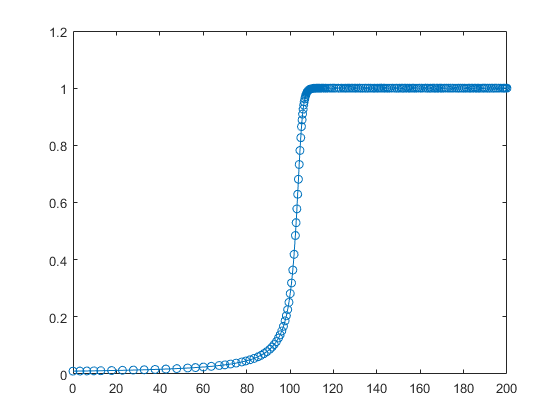

delta = 0.01;
F = @(t,y) y^2 - y^3;
opts = odeset('RelTol',1.e-4);
ode45(F,[0 2/delta],delta,opts);

set(gcf,'Color','w')

ode45对付刚性的表现

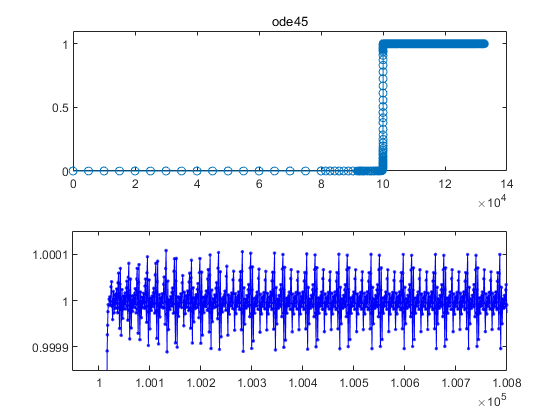

figure
delta = 0.00001;
ode45(F,[0 2/delta],delta,opts);
set(gcf,'Color','w')
Ax0=gca;
lin=Ax0.Children;
X=lin.XData;Y=lin.YData;
L=X>1e5 & X<1.07e5;
x=X(L);y=Y(L);
subplot(2,1,1,Ax0)
title('ode45')
ylim([0,1.1])
subplot(2,1,2)
plot(x,y,'.b-')
ylim([0.99985,1.00015])
xlim([0.9995,1.008]*10^5)

ode23s对付刚性

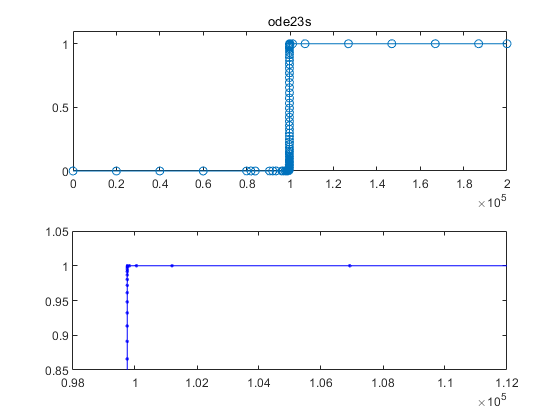

figure
delta = 0.00001;
ode23s(F,[0 2/delta],delta,opts);
set(gcf,'Color','w')
Ax0=gca;
lin=Ax0.Children;
X=lin.XData;Y=lin.YData;
L=X>0.99e5 & X<1.5e5;
x=X(L);y=Y(L);
subplot(2,1,1,Ax0)
title('ode23s')
ylim([0,1.1])
subplot(2,1,2)
plot(x,y,'.b-')
ylim([0.85,1.05])
xlim([0.98,1.12]*10^5)

火焰方程

syms y(x)
Dy=diff(y,x);
y=dsolve(Dy==y^2-y^3,y(0)==1/100);
y=simplify(y)

$$y = \frac{1}{W_{0}\left(99\,{\mathrm{e}}^{99-x}\right)+1}$$

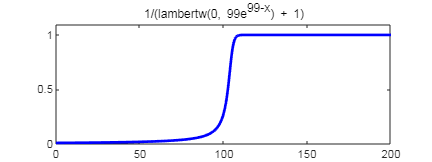

F=figure;
FP=F.Position;
F.Position=[FP(1:3),FP(4)/2];
fplot(y,[0,200],'Color','b','LineWidth',2)
ylim([0,1.1])
ss=replace(char(y),'*exp(99 - x)','e^{99-x}');
title(ss)